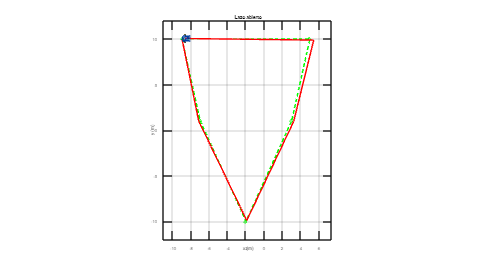

%MARIAM LANDA BAUTISTA A01736672
% CONTROL EN LAZO ABIERTOSS
clear all
close all
clc
% Tiempo de muestreo
ts = 0.1;
% Valores fijos de velocidad lineal y angular para el movimiento del robot
u_val = 1.0;
w_val = 0.5;

puntos = [-9 10;
          -7 1;
          -2 -10;
           3 1;
           5 10;
          -9 10];

% Se inicializa la posición del robot con el primer punto
x1(1) = puntos(1,1);
y1(1) = puntos(1,2);
phi(1) = -pi/2;

% Vectores que almacenarán la trayectoria completa del robot
hx(1) = x1(1); 
hy(1) = y1(1);


% Vectores de control: velocidades lineales y angulares aplicadas
u = []; 
w = [];

for i = 1:size(puntos,1)-1
    ang_obj = atan2(puntos(i+1,2)-puntos(i,2), puntos(i+1,1)-puntos(i,1));
    delta_ang = wrapToPi(ang_obj - phi(end));
    t_giro = abs(delta_ang / w_val);
    N_giro = round(t_giro / ts);

    u = [u, zeros(1,N_giro)];
    w = [w, sign(delta_ang)*w_val*ones(1,N_giro)];
    phi_temp = phi(end);
    for k = 1:N_giro
        phi_temp = phi_temp + sign(delta_ang)*w_val*ts;
        phi(end+1) = phi_temp;
        x1(end+1) = x1(end);
        y1(end+1) = y1(end);
        hx(end+1) = x1(end);
        hy(end+1) = y1(end);
    end

    dist = norm(puntos(i+1,:) - [x1(end), y1(end)]);
    t_avance = dist / u_val;
    N_avance = round(t_avance / ts);

    u = [u, u_val*ones(1,N_avance)];
    w = [w, zeros(1,N_avance)];
    for k = 1:N_avance
        phi(end+1) = phi(end);
        x1(end+1) = x1(end) + u_val*cos(phi(end))*ts;
        y1(end+1) = y1(end) + u_val*sin(phi(end))*ts;
        hx(end+1) = x1(end);
        hy(end+1) = y1(end);
    end
end

% -------- 5. ANIMACIÓN VIRTUAL 3D --------
N = length(hx);  % longitud de la trayectoria generada

figure;
set(gcf, 'Color', 'white', 'Position', get(0,'ScreenSize')); % Configurar pantalla completa
camlight('headlight');
axis equal; grid on; box on;
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
title(['Lazo abierto'], 'FontWeight', 'bold');
view([-0.1 90]);  % Vista superior

% Coordenadas deseadas
hxd = puntos(:,1)';
hyd = puntos(:,2)';

% Ajustar límites con margen
padding = 2;
minX = min([hx, hxd]) - padding;
maxX = max([hx, hxd]) + padding;
minY = min([hy, hyd]) - padding;
maxY = max([hy, hyd]) + padding;
axis([minX maxX minY maxY 0 1]);

% Representar robot y trayectorias
scale = 5;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);  % Trayectoria real
H3 = plot3(hxd, hyd, zeros(1,length(hxd)), 'g--o', 'LineWidth', 2);  % Trayectoria deseada

% Animación paso a paso
step = 5;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

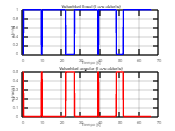


t = 0:ts:(length(u)-1)*ts;
figure;
subplot(2,1,1)
plot(t,u,'b','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('u [m/s]'),title('Velocidad lineal (Lazo abierto)')
subplot(2,1,2)
plot(t,w,'r','LineWidth',2),grid on
xlabel('Tiempo [s]'),ylabel('w [rad/s]'),title('Velocidad angular (Lazo abierto)')

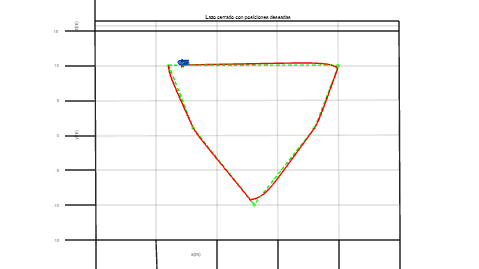


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PARTE 2: LAZO CERRADO CON POSICIONES DESEADAS (CONTROL DE POSICIÓN)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clearvars -except MobileRobot_5 MobilePlot_4
clc

% Tiempo de muestreo y duración total de la simulación
ts = 0.1;
tf = 50;
t = 0:ts:tf;
N = length(t);

% Puntos deseados por los que debe pasar el robot (misma secuencia)
puntos = [-9 10;
          -7 1;
          -2 -10;
           3 1;
           5 10;
          -9 10];

% Estado inicial del robot: en el primer punto, orientación hacia abajo
x1(1) = puntos(1,1);
y1(1) = puntos(1,2);
phi(1) = -pi/2;

% Inicialización de vectores de trayectoria y control
hx(1) = x1(1); 
hy(1) = y1(1);
v = zeros(1,N);     % Velocidad lineal
w = zeros(1,N);     % Velocidad angular
Error = zeros(1,N); % Error de posición

idx_objetivo = 1;
umbral = 0.5;
num_puntos = size(puntos,1);

% Bucle de simulación para el control de posición
for k = 1:N

     % Coordenadas del punto objetivo actual
    hxd = puntos(idx_objetivo,1);
    hyd = puntos(idx_objetivo,2);

    % Calculamos el error entre la posición actual y la deseada
    hxe = hxd - hx(k);
    hye = hyd - hy(k);
    he = [hxe; hye];
    Error(k) = norm(he);

    % Si el error es pequeño, pasamos al siguiente punto
    if Error(k) < umbral && idx_objetivo < num_puntos
        idx_objetivo = idx_objetivo + 1;
    end

    % Matriz de transformación para expresar el error en el marco del robot
    J = [cos(phi(k)) -sin(phi(k));
         sin(phi(k))  cos(phi(k))];

    % Matriz de ganancias para control proporcional
    K = [0.3 0; 0 0.3];

    qpRef = pinv(J) * K * he;
    v(k) = qpRef(1);
    w(k) = qpRef(2);

    phi(k+1) = phi(k) + w(k)*ts;
    x1(k+1) = x1(k) + v(k)*cos(phi(k))*ts;
    y1(k+1) = y1(k) + v(k)*sin(phi(k))*ts;
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

% -------- ANIMACIÓN 3D --------
scene = figure;
set(scene,'Color','white','position',get(0,'ScreenSize'));
camlight('headlight');
axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
title(['Lazo cerrado con posiciones deseadas'], 'FontWeight', 'bold');
view([-0.1 35]);
axis([-15 10 -15 15 0 1]);

% Trajectoria deseada
hxd_full = puntos(:,1)';
hyd_full = puntos(:,2)';

scale = 5;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);
H3 = plot3(hxd_full, hyd_full, zeros(1,length(hxd_full)), 'g--o', 'LineWidth', 2);

step = 5;
for k = 1:step:N
    delete(H1);
    delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

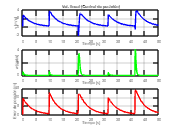


figure;
subplot(3,1,1)
plot(t,v,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'); ylabel('v [m/s]'); title('Vel. lineal (Control de posición)')
subplot(3,1,2)
plot(t,w,'g','LineWidth',2), grid on
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
subplot(3,1,3)
plot(t,Error(1:N),'r','LineWidth',2), grid on
xlabel('Tiempo [s]'); ylabel('Error de posición [m]');

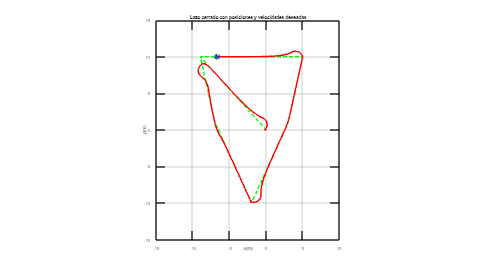


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PARTE 3: LAZO CERRADO CON POSICIÓN Y VELOCIDAD DESEADA (CONTROL DE TRAYECTORIA)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clearvars -except MobileRobot_5 MobilePlot_4
clc

% Tiempo total de simulación y resolución temporal
tf = 50;
ts = 0.05;
t = 0:ts:tf;
N = length(t);

% Estado inicial del robot
x1(1) = 0; 
y1(1) = 0; 
phi(1) = 0;

% Inicialización de trayectoria real
hx(1) = x1(1); 
hy(1) = y1(1);

puntos = [ 0   0;
          -9  10;
          -7   1;
          -2 -10;
           3   1;
           5  10;
          -9  10];

num_segmentos = size(puntos,1)-1;
puntos_por_segmento = floor(N / num_segmentos);
hxd = zeros(1,N); hyd = zeros(1,N);
ti = 1;

for i = 1:num_segmentos
    if i == num_segmentos
        tf_i = N;
    else
        tf_i = ti + puntos_por_segmento - 1;
        if tf_i > N
            tf_i = N;
        end
    end
    x_segment = linspace(puntos(i,1), puntos(i+1,1), tf_i - ti + 1);
    y_segment = linspace(puntos(i,2), puntos(i+1,2), tf_i - ti + 1);
    hxd(ti:tf_i) = x_segment;
    hyd(ti:tf_i) = y_segment;
    ti = tf_i + 1;
end

hxdp = [diff(hxd)/ts, 0];
hydp = [diff(hyd)/ts, 0];

for k = 1:N
    hxe(k) = hxd(k) - hx(k);
    hye(k) = hyd(k) - hy(k);
    he = [hxe(k); hye(k)];
    Error(k) = norm(he);

    J = [cos(phi(k)) -sin(phi(k));
         sin(phi(k))  cos(phi(k))];
    K = [10 0; 0 10];

    hdp = [hxdp(k); hydp(k)];
    qpRef = pinv(J)*(hdp + K*he*tanh(norm(he)));
    v(k) = max(min(qpRef(1), 1.5), -1.5);
    w(k) = max(min(qpRef(2), 1.5), -1.5);

    if k > N-20 && Error(k) < 0.3
        v(k) = 0;
        w(k) = 0;
    end

    phi(k+1) = phi(k) + w(k)*ts;
    x1(k+1) = x1(k) + ts*v(k)*cos(phi(k));
    y1(k+1) = y1(k) + ts*v(k)*sin(phi(k));
    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

% 5. ANIMACIÓN VIRTUAL 3D
scene = figure;
set(scene,'Color','white','Position',get(0,'ScreenSize'));
camlight('headlight'); axis equal; grid on; box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');
title('Lazo cerrado con posiciones y velocidades deseadas');
view([-0.1 90]); axis([-15 10 -15 15 0 1]);

% Trayectorias
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1), y1(1), phi(1), scale); hold on;
H2 = plot3(hx(1), hy(1), 0, 'r', 'LineWidth', 2);
H3 = plot3(hxd, hyd, zeros(1,N), 'g--', 'LineWidth', 2);

% Animación paso a paso
step = 5;
for k = 1:step:N
    delete(H1); delete(H2);
    H1 = MobilePlot_4(x1(k), y1(k), phi(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

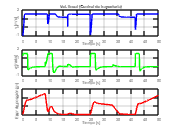


figure;
subplot(3,1,1)
plot(t,v,'b','LineWidth',2), grid on
xlabel('Tiempo [s]'); ylabel('v [m/s]'); title('Vel. lineal (Control de trayectoria)')
subplot(3,1,2)
plot(t,w,'g','LineWidth',2), grid on
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
subplot(3,1,3)
plot(t,Error(1:N),'r','LineWidth',2), grid on
xlabel('Tiempo [s]'); ylabel('Error de posición [m]');

% ------------------------- ESTRATEGIA 1: CONTROL ABIERTO -------------------------

% El robot actúa siguiendo un conjunto fijo de comandos sin considerar su posición real.

% Ventajas:

% + Código simple y directo

% + No se requieren sensores ni cálculos de retroalimentación

% Desventajas:

% - No se ajusta ante desviaciones

% - Puede acumular errores significativos

% - Afectado por perturbaciones externas

% ---------------------- ESTRATEGIA 2: CONTROL POR POSICIÓN ----------------------

% El robot compara su estado con un punto objetivo y corrige en base al error.

% Ventajas:

% + Mejora la precisión respecto al control abierto

% + Permite correcciones en línea

% + Adecuado para trayectorias punto a punto

% Desventajas:

% - La trayectoria puede ser discontinua

% - Requiere buen ajuste de ganancias para evitar inestabilidad

% --------------- ESTRATEGIA 3: CONTROL POR TRAYECTORIA CONTINUA ---------------

% Se siguen posiciones y velocidades deseadas, generando un movimiento fluido.

% Ventajas:

% + Trayectoria más suave y precisa

% + Permite un control más realista y eficiente

% + Ideal para trayectorias interpoladas o planificadas matemáticamente

% Desventajas:

% - Mayor complejidad en el diseño

% - Requiere planificación y parametrización previa

% - Puede tener errores al iniciar si la referencia no es suave